%Experiment Number 2 - Curve Fitting
% Name of Programmer - Sahil Patra
% Roll No- 124MM0055
clc
clear all
n=input("Enter Number of Data Points ");
x = zeros(1, n);
y = zeros(1, n);
for i = 1:n
    x(i) = input('X= \n');
    y(i) = input('Y= \n');
end
sum_x = 0;
sum_y = 0;
sum_2_x = 0;
sum_x_y = 0;
sum_3_x = 0;
sum_4_x = 0;
sum_2_x_y = 0;

for i = 1:n
    sum_x = sum_x + x(i);
    sum_y = sum_y + y(i);
    sum_2_x = sum_2_x + x(i)^2;
    sum_x_y = sum_x_y + x(i) * y(i);
    sum_3_x = sum_3_x + x(i)^3;
    sum_4_x = sum_4_x +x(i)^4;
    sum_2_x_y = sum_2_x_y + (x(i)^2)*y(i);
   
end
A=[sum_2_x sum_x n;
    sum_3_x sum_2_x sum_x;
    sum_4_x sum_3_x sum_2_x];
B=[sum_y; 
    sum_x_y;
    sum_2_x_y];
X=A\B;
a = X(1);
b = X(2);
c = X(3);
fprintf('Best Fit Second Degree Curve y = %fx^2+%fx+%f ', a,b,c)

Best Fit Second Degree Curve y = 0.550000x^2+-1.070000x+1.420000 

figure(1)
scatter(x,y,"filled")
hold on
y_fitted=a*x.^2+b*x+c;
plot(x,y_fitted)
% Goodness of fit 
y_mean= sum_y/n;
SS_res = sum((y - y_fitted).^2); 
SS_tot = sum((y - y_mean).^2);   
G= (SS_tot-SS_res)/SS_tot;
fprintf('Goodness of Fit : %f\n', G);

Goodness of Fit : 0.914784


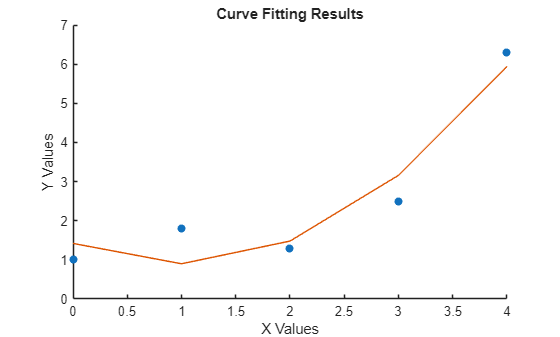

xlabel('X Values');
ylabel('Y Values');
title('Curve Fitting Results');